# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 03-May-2024 21:26:23

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\mehme\Desktop\Derin öğrenme ekran\MyCNNensondaki\params_2024_05_03__21_25_41.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\mehme\Desktop\derin öğrenme ödevi\archive\Alzheimer_s Dataset\train","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("rmsprop",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.0001,...
    "LearnRateDropPeriod",3,...
    "MaxEpochs",15,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",30,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([227 227 1],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([3 3],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([3 3],"Name","maxpool_3","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_4")
    maxPooling2dLayer([3 3],"Name","maxpool_4","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_5")
    maxPooling2dLayer([3 3],"Name","maxpool_5","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_6","Padding","same")
    reluLayer("Name","relu_6")
    maxPooling2dLayer([3 3],"Name","maxpool_6","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_7","Padding","same")
    reluLayer("Name","relu_7")
    maxPooling2dLayer([3 3],"Name","maxpool_7","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_8","Padding","same")
    reluLayer("Name","relu_8")
    maxPooling2dLayer([3 3],"Name","maxpool_8","Padding","same")
    fullyConnectedLayer(4,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:35 |        7.81% |       49.97% |       1.9433 |     271.8206 |      1.0000e-04 |
|       1 |           2 |       00:00:49 |       56.25% |              |     234.8029 |              |      1.0000e-04 |
|======================================================================================================================|
Training finished: Stopped manually.


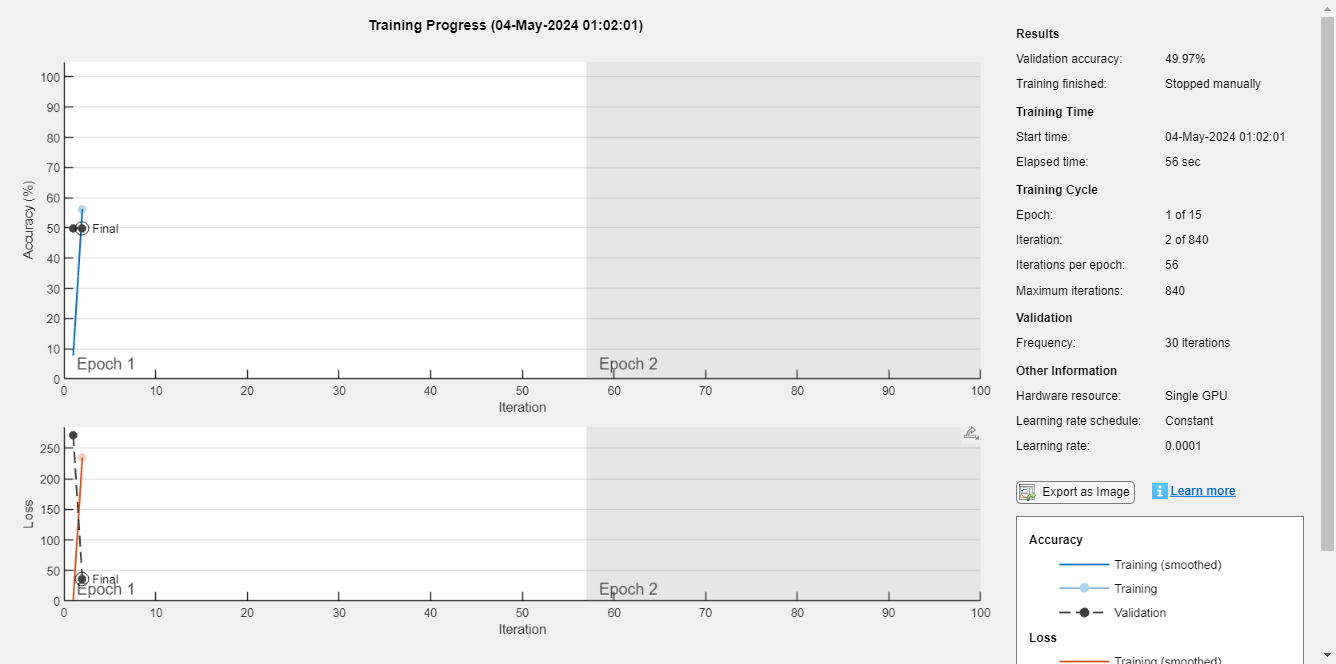

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);